# SEIQR Model Simulation

Copyright 2022 Justice Inkoom at University of Mines and Technology

This is a simple **SEIQR** model of disease spread, implemented in MATLAB®. This approach is widely used to analyze infection data during the different stages of an epidemic outbreak. The population is divided into Susceptible (S), Exposed (E), Infectious (I), Quarantined (Q), and Recovered (R) individuals.

This particular model with its parameters are based on covid-19 outbreak in Ghana.

## The Model Overview

The equations that make up the SEIQR model are described by 5 ordinary differential equations as follows:


$$\begin{array}{l}
\frac{\textrm{ds}}{\textrm{dt}}=\alpha -\beta \ldotp s\ldotp \left(i+q\right)-\mu \ldotp s\\
\frac{\textrm{de}}{\textrm{dt}}=\beta \ldotp s\ldotp \left(i+q\right)-\left(\mu +\kappa +\gamma_2 +\nu \right)\ldotp e\\
\frac{\textrm{di}}{\textrm{dt}}=\kappa \ldotp e-\left(\mu +\delta_2 +\gamma_1 +\psi \right)\ldotp i\\
\frac{\textrm{dq}}{\textrm{dt}}=\nu \ldotp e+\psi \ldotp i-\left(\mu +\delta_1 +\gamma_3 \right)\ldotp q\\
\frac{\textrm{dr}}{\textrm{dt}}=\gamma_1 \ldotp i+\gamma_2 \ldotp e+\gamma_3 \ldotp q-\mu \ldotp r
\end{array}$$


## Model Simulation

**Model Parameters**

Play around with the parameters using the sliders and see the effect on the plot.

%% Initial parameters
a = 0.00007;     %rate at which a baby is born into a susceptible class
B = 0.02500;     %exrate at which a person is exposed to the Covid-19 infection
k = 0.07142;     %rate at which an exposed persone becomes infected with Covid-19 virus
d_1 = 0.0008;    %rate at which quarantined person dies from his or her Covid-19 infection
d_2 = 0.00729;   %rate at which an infected person dies from his or her Covid-19 infection
v = 0.01430;     %rate at which an exposed person is quarantined
g_1 = 0.00025;   %rate at which an infected person recovers from his or her Covid-19 infection
g_2 = 0.00051;   %rate at which an exposed person recovers from his or her Covid-19 infection
g_3 = 0.00178;   %rate at which a quarantined person recovers from his or her Covid-19 infection
phi = 0.00288;   %rate at which an infected person is quarantined
u = 0.00002;

S0 = 0.95631246;          %initial proportion of Susceptible
E0 = 3.6448*(10^(-02));   %initial proportion of Exposed
I0 = 3.0487*(10^(-03));   %initial proportion of Infected
Q0 = 1.2195*(10^(-03));   %initial proportion of Quarantined
R0 = 2.9709*(10^(-03));

**Solve the ODE using **[ode45](https://www.mathworks.com/help/matlab/ref/ode45.html).

y0 = [S0; E0; I0; Q0; R0];                % Initial conditions
T = 2500;
tspan = [0 T];                        % Interval of Integration
[t,y] = ode45(@(t,y) seiqr_model(t,y,a,B,k,d_1,d_2,v,g_1,g_2,g_3,phi,u),tspan,y0);

For more info see the [Anonymous functions documentation](http://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html).

**Plots that show the results**

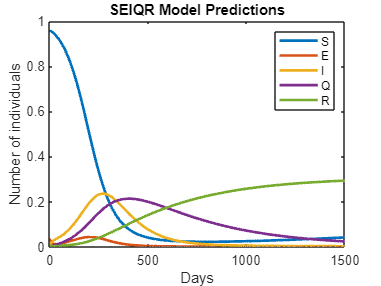

plot(t,y,'LineWidth',2);
xlabel('Days'); 
ylabel('Number of individuals');
legend('S','E','I', 'Q','R');
title('SEIQR Model Predictions');

For more info see the [plot documentation](https://www.mathworks.com/help/matlab/ref/plot.html).

**Function **`seir_model`** that calculates the model evolution over a time period T.**

function dydt = seiqr_model(t,y,a,B,k,d_1,d_2,v,g_1,g_2,g_3,phi,u)
  S = y(1);
  E = y(2);
  I = y(3);
  Q = y(4);
  R = y(5);
  % Equations of the model described above
  dS = (a-(B*S)*(I+Q)-(u*S)) ;
  dE = ((B*S)*(I+Q)-(u+k+g_2+v)*E) ;
  dI = ((k*E)-(u+d_2+g_1+phi)*I);
  dQ = ((v*E)+(phi*I)-(u+d_1+g_3)*Q);
  dR = ((g_1*I)+(g_2*E)+(g_3*Q)-(u*R));
  dydt = [dS;dE;dI;dQ;dR];
end

## Further Evaluation

The three critical parameters in the model are beta, lambda and gamma.

Note that we have left several features unmodeled, for example: 

- Immunity loss rate ($\left.\alpha \right)$, where recovered individuals can get infected again.

- Some exposed individuals in "E" might move directly to the "R" category;

-  Some infected individuals in category "I" might not gain perfect immunity and so may move back to susceptible category "S." 

Despite these limitations, this basic SEIR model can provide some useful insights on the disease evolution.

  **Task.** Include additional features to your model and observe the effect on the plot.

                Example: To include Immunity loss rate ($\left.\alpha \right)$, the equations will be as follows:

                
$$\begin{array}{l}
\frac{\textrm{dS}}{\textrm{dt}}=-\beta \cdot \mathrm{S}\cdot \frac{I}{N}+\alpha \cdot \mathrm{R}\\
\frac{\textrm{dE}}{\textrm{dt}}=\beta \cdot \mathrm{S}\cdot \frac{I}{N}-\lambda \cdot E\\
\frac{\textrm{dI}}{\textrm{dt}}=\lambda \cdot E-\gamma \cdot \mathrm{I}\\
\frac{\textrm{dR}}{\textrm{dt}}=\gamma \cdot \mathrm{I}-\alpha \cdot \mathrm{R}
\end{array}$$
